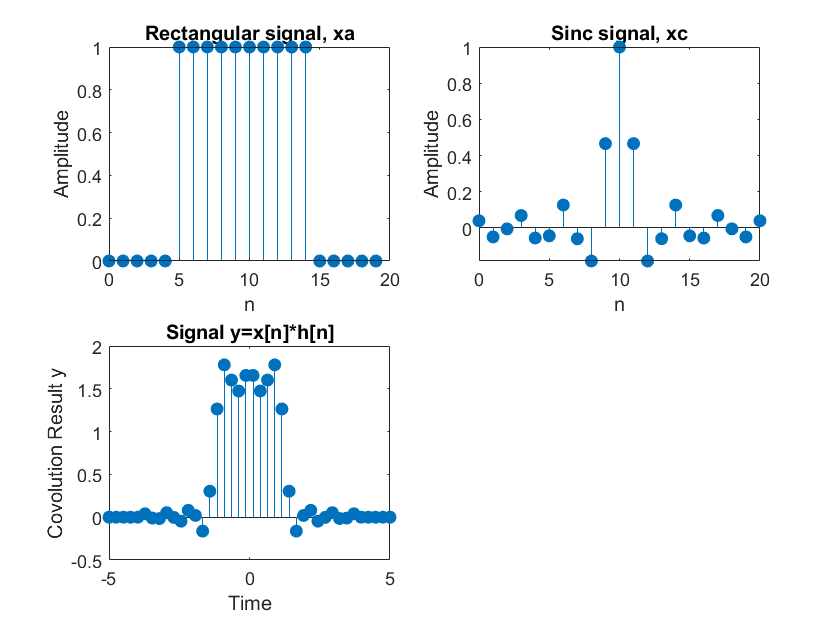

% Common signals
clear;
%% Signal xa 
La = 20; %Signanl length (no. of samples)
na = [0:La-1]; %Signal sample index
xa = [zeros(1, La/4) ones(1,La/2), zeros(1,La/4)];
figure(1);
subplot(2,2,1);
%plotting
stem(na, xa ,'filled'); %Plotting of signal 
xlabel('n'); ylabel('Amplitude'); title('Rectangular signal, xa'); %Plotting of signal

%% Signal xc
Lc = 21; %Signal length (no. of samples)
nc = [0:Lc-1]; %Signal sample index
ang_d = 0.2*pi; %Phase angle per sampling period
n_temp = [1:floor(Lc/2)]; 
x_temp = sinc(ang_d*n_temp); %Half side of signal
x_temp1 = fliplr(x_temp); %Flip x_temp left-right to generate the other half 
xc = [x_temp1 1 x_temp]; %combining both halves and 1 at centre

subplot(2,2,2); %Use subplot %Sub-divide figure into 2X2 = 4 plots and set plot 3 for plotting
stem(nc, xc ,'filled'); %Use stem %Plotting of signal with discrete samples
xlabel('n'); ylabel('Amplitude'); title('Sinc signal, xc'); %Plotting of signal



%Convolution between x[n] and h[n]
y = conv(xa,xc);
tc = linspace(-5,5,length(y)); %Time vector for convoluted signal
subplot(2,2,3)
stem(tc,y,'filled')
xlabel('Time')
ylabel('Covolution Result y')
title('Signal y=x[n]*h[n]')